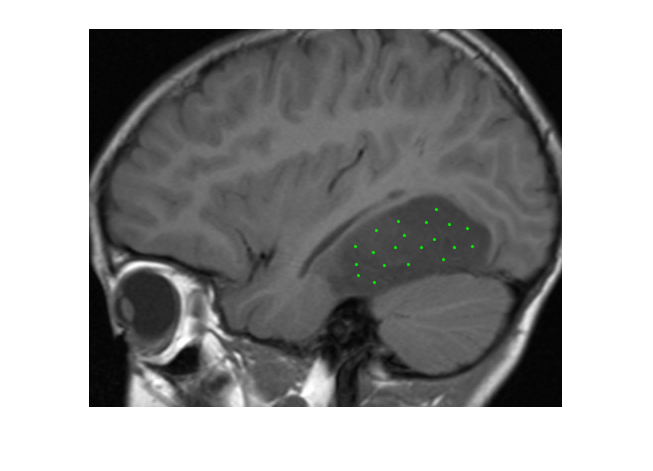

%Load dataset
Im = load("tumorData.mat");
Im = Im.data;
%Load selected tumor points
SelPoints = cell2mat(struct2cell(load("SelPoints.mat"))');
xSelPoints = round(SelPoints(:, 1));
ySelPoints = round(SelPoints(:, 2));
%Visualize the selected points 
figure();
imshow(Im, [])
hold on;
plot(xSelPoints, ySelPoints, '.g')
hold off;

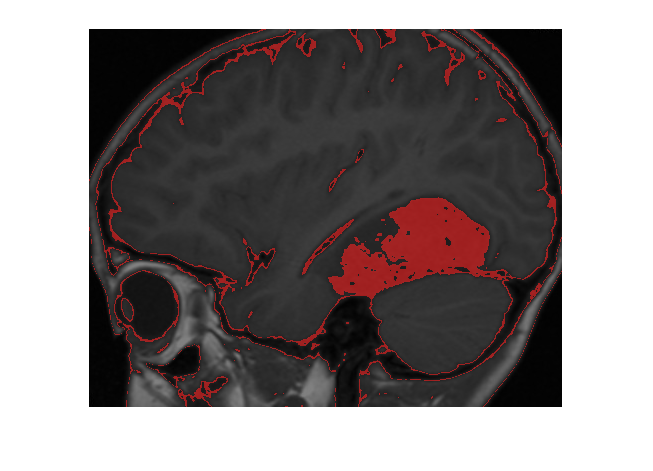

%Calculate the mean and standard deviation of the intensities of selected points
ImSelIntensity = diag(Im(ySelPoints, xSelPoints));
tumorMean = mean(ImSelIntensity);
tumorVar = var(ImSelIntensity);
%Calculate the mean and standard deviation of all image intensities
ImMean = mean(Im(:));
ImVar = var(Im(:));

%Define the prior probabilities
pi = [0.2 0.8];

%Calculate posterior probabilities
posteriorLab1 = normpdf(Im, tumorMean, sqrt(tumorVar)) * pi(1) ./ (normpdf(Im, tumorMean, sqrt(tumorVar)) * pi(1) ...
    + normpdf(Im, ImMean, sqrt(ImVar)) * pi(2));

%Since there are only 2 classes, the posterior probability of the 2nd class
%can be calculates as 1 - P
posteriorLab2 = 1 - posteriorLab1;
rgb = zeros([size(Im) 3]);
rgb(:, :, 1) = posteriorLab1 > posteriorLab2;
ImFused = imfuse(Im, rgb, 'blend');
imshow(ImFused)


% se1 = strel("diamond", 6);
% se2 = strel("square", 2);
% rgb = imclose(rgb, se2);
% rgb = imopen(rgb, se1);
% rgb = imclose(rgb, se1);


%Set the Gaussian posterior as distribution q of the tumor class and
%creaate a matrix with number of nieghbours assigned to a different class
qOfClass1 = posteriorLab1;
nonPadded = 1 - qOfClass1;
padded = zeros(size(nonPadded) + 2);
padded(2:end-1, 2:end-1) = nonPadded;
numOfDiffNeigh1 = ...
    padded((2 : end-1) - 1, (2 : end-1) ) + ...
    padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] ) + ...
    padded( [ 2 : end-1 ], [ 2 : end-1 ] + 1 ) + ...
    padded( [ 2 : end-1 ], [ 2 : end-1 ] - 1 ) + ...
    padded( [ 2 : end-1 ] - 1, [ 2 : end-1 ] - 1 ) + ...
    padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] - 1 ) + ...
    padded( [ 2 : end-1 ] - 1, [ 2 : end-1 ] + 1 ) + ...
    padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] + 1 )

numOfDiffNeigh1 =      3     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     5     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8
     5     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8
     5     8     8     8     8     8     8     8     8     8     8     8     8 

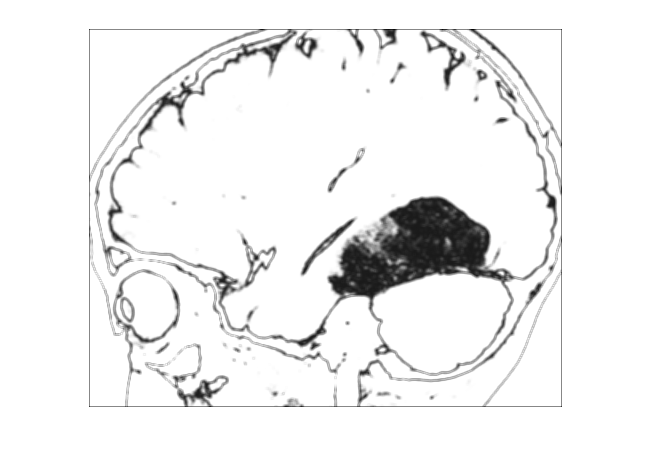

imshow(numOfDiffNeigh1, [])


qOfClass2 = posteriorLab2;
nonPadded = 1 - qOfClass2;
padded = zeros(size(nonPadded) + 2);
padded(2:end-1, 2:end-1) = nonPadded;
numOfDiffNeigh2 = ...
    padded((2 : end-1) - 1, (2 : end-1) ) + ...
    padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] ) + ...
    padded( [ 2 : end-1 ], [ 2 : end-1 ] + 1 ) + ...
    padded( [ 2 : end-1 ], [ 2 : end-1 ] - 1 ) + ...
    padded( [ 2 : end-1 ] - 1, [ 2 : end-1 ] - 1 ) + ...
    padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] - 1 ) + ...
    padded( [ 2 : end-1 ] - 1, [ 2 : end-1 ] + 1 ) + ...
    padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] + 1 )

numOfDiffNeigh2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0 

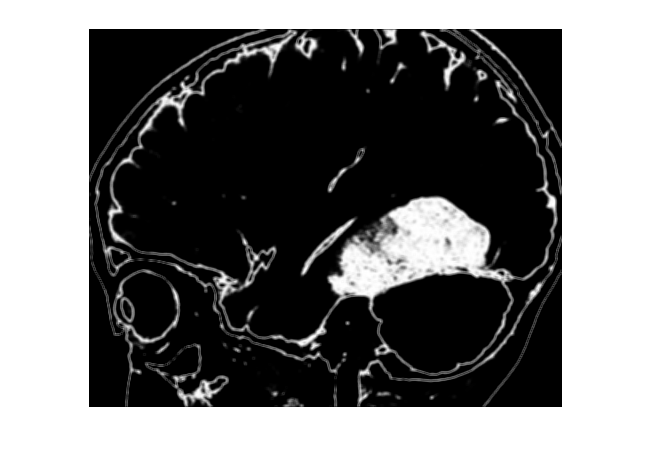

imshow(numOfDiffNeigh2, [])

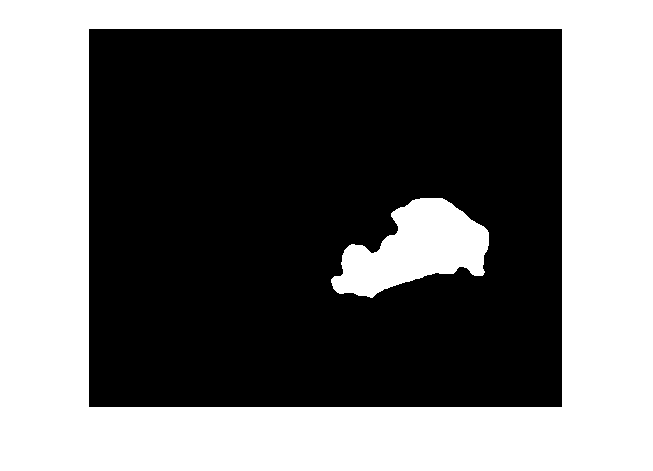

%Define the penalization parameter Beta and obtain 
%indices of each of the non-neighbouring pixels to update
Beta = 2.5;
tmp1 = ones(size(Im, 1), 1);
tmp1( 1 : 2 : end ) = 0;
tmp2 = ones( 1, size(Im, 2 ) );
tmp2( 1 : 2 : end ) = 0;
whiteIndices = find( kron( tmp1, tmp2 ) );
blackIndices = find( kron( ~tmp1, ~tmp2 ) );
redIndices = find( kron( ~tmp1, tmp2 ) );
greenIndices = find( kron( tmp1, ~tmp2 ) );

indicesToUpdateCell{1} = whiteIndices;
indicesToUpdateCell{2} = blackIndices;
indicesToUpdateCell{3} = redIndices;
indicesToUpdateCell{4} = greenIndices;

%Set the initial approximation of distributions
qOfClass1 = posteriorLab1;
qOfClass2 = posteriorLab2;

for k = 1:100
    %Create matrices which calculate the number of neighbours
    %that are different from each of the classes
    nonPadded = 1 - qOfClass1;
    padded = zeros(size(nonPadded) + 2);
    padded(2:end-1, 2:end-1) = nonPadded;
    numOfDiffNeigh1 = ...
        padded( [ 2 : end-1 ] - 1, [ 2 : end-1 ] ) + ...
        padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] ) + ...
        padded( [ 2 : end-1 ], [ 2 : end-1 ] + 1 ) + ...
        padded( [ 2 : end-1 ], [ 2 : end-1 ] - 1 ) + ...
        padded( [ 2 : end-1 ] - 1, [ 2 : end-1 ] - 1 ) + ...
        padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] - 1 ) + ...
        padded( [ 2 : end-1 ] - 1, [ 2 : end-1 ] + 1 ) + ...
        padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] + 1 );
    nonPadded = 1 - qOfClass2;
    padded = zeros(size(nonPadded) + 2);
    padded(2:end-1, 2:end-1) = nonPadded;
    numOfDiffNeigh2 = ...
        padded((2 : end-1) - 1, (2 : end-1) ) + ...
        padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] ) + ...
        padded( [ 2 : end-1 ], [ 2 : end-1 ] + 1 ) + ...
        padded( [ 2 : end-1 ], [ 2 : end-1 ] - 1 ) + ...
        padded( [ 2 : end-1 ] - 1, [ 2 : end-1 ] - 1 ) + ...
        padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] - 1 ) + ...
        padded( [ 2 : end-1 ] - 1, [ 2 : end-1 ] + 1 ) + ...
        padded( [ 2 : end-1 ] + 1, [ 2 : end-1 ] + 1 );
    %Update each of the non-neighbouring posterior probability grids
    for colorIndex = 1:4
        indicesToUpdate = indicesToUpdateCell{colorIndex};
        tmpNeighbour1 = numOfDiffNeigh1(indicesToUpdate);
        tmpNeighbour2 = numOfDiffNeigh2(indicesToUpdate);
        GammaLab1 = (pi(1) * exp(-Beta * tmpNeighbour1)) ./ ...
            (pi(1) * exp(-Beta * tmpNeighbour1) + pi(2) * exp(-Beta * tmpNeighbour2));
        GammaLab2 = pi(2) * exp(-Beta * tmpNeighbour2) ./ ...
            (pi(1) * exp(-Beta * tmpNeighbour1) + pi(2) * exp(-Beta * tmpNeighbour2));
        ImTmp = Im(indicesToUpdate);
        tmp1 = normpdf(ImTmp, tumorMean, sqrt(tumorVar)) .* GammaLab1 ./ (normpdf(ImTmp, tumorMean, sqrt(tumorVar)) ...
            .* GammaLab1 + normpdf(ImTmp, ImMean, sqrt(ImVar)) .* GammaLab2);
        tmp2 = normpdf(ImTmp, ImMean, sqrt(ImVar)) .* GammaLab2 ./ (normpdf(ImTmp, tumorMean, sqrt(tumorVar)) ...
            .* GammaLab1 + normpdf(ImTmp, ImMean, sqrt(ImVar)) .* GammaLab2);
        
        qOfClass1(indicesToUpdate) = tmp1;
        qOfClass2(indicesToUpdate) = tmp2;
    end
end
imshow(qOfClass1 > qOfClass2, [])